clf
X_positions = []


X_positions =

     []



Y_positions = []


Y_positions =

     []



Z_positions = []


Z_positions =

     []



robot_positions = []


robot_positions =

     []



position_errors = []


position_errors =

     []



folders = ["109","208","262","280"]

folders = 1×4 string array
    "109"    "208"    "262"    "280"


mean_robot_positions = []


mean_robot_positions =

     []



mean_robot_positions = []


mean_robot_positions =

     []



position_deviations = []


position_deviations =

     []



for j = 1:length(folders)
    robot_positions = [];
    position_cloud = [];
    prefix = folders(j)
    for i =1 : 3
        name = prefix+'\robot_motion_pt_'+prefix+'_' +string(i)+'.bag'
        bag = rosbag(name);
    
        bSel = select(bag,'Topic','/tool_link_ee_pose')
        % 
        msgStructs = readMessages(bSel,'DataFormat','struct');
        
        X = msgStructs{bSel.NumMessages,1}.Transform.Translation.X;
        Y = msgStructs{bSel.NumMessages,1}.Transform.Translation.Y
        Z = msgStructs{bSel.NumMessages,1}.Transform.Translation.Z;
        robot_positions = [robot_positions;X Y Z]
        
        
        name = prefix+'/pose_normal_pt_'+prefix+'_'+string(i)+'.bag'
        bag = rosbag(name);
        
        bSel = select(bag,'Topic','/tf_array_out');
        msgStructs = readMessages(bSel,'DataFormat','struct');
        x = msgStructs{bSel.NumMessages,1}.Poses.Position.X;
        y = msgStructs{bSel.NumMessages,1}.Poses.Position.Y;
        z = msgStructs{bSel.NumMessages,1}.Poses.Position.Z;
        
        position_cloud = [position_cloud ; x y z]
        
        
    %     error_orientation = abs(robot_orientation_euler_deg -mean_rpy)
        
        
    end
    error_position = mean(robot_positions - position_cloud)*1000
    position_errors = [position_errors;error_position]
    std_error_position = std(robot_positions - position_cloud)*1000
    position_deviations = [position_deviations;std_error_position]

end

prefix = "109"

name = "109\robot_motion_pt_109_1.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\109\robot_motion_pt_109_1.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 466
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [466×4 table]


Y = 0.0744

robot_positions =    -0.7061    0.0744    0.2025


name = "109/pose_normal_pt_109_1.bag"

position_cloud =    -0.7113    0.0819    0.1962


name = "109\robot_motion_pt_109_2.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\109\robot_motion_pt_109_2.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 593
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [593×4 table]


Y = 0.0724

robot_positions =    -0.7061    0.0744    0.2025
   -0.6833    0.0724    0.2030


name = "109/pose_normal_pt_109_2.bag"

position_cloud =    -0.7113    0.0819    0.1962
   -0.6857    0.0780    0.1979


name = "109\robot_motion_pt_109_3.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\109\robot_motion_pt_109_3.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 761
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [761×4 table]


Y = 0.0763

robot_positions =    -0.7061    0.0744    0.2025
   -0.6833    0.0724    0.2030
   -0.6918    0.0763    0.1987


name = "109/pose_normal_pt_109_3.bag"

position_cloud =    -0.7113    0.0819    0.1962
   -0.6857    0.0780    0.1979
   -0.6945    0.0725    0.1971


error_position =     3.4862   -3.1090    4.3395


position_errors =     3.4862   -3.1090    4.3395


std_error_position =     1.5580    6.0124    2.4466


position_deviations =     1.5580    6.0124    2.4466


prefix = "208"

name = "208\robot_motion_pt_208_1.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\208\robot_motion_pt_208_1.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 696
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [696×4 table]


Y = -0.0566

robot_positions =    -0.6872   -0.0566    0.2011


name = "208/pose_normal_pt_208_1.bag"

position_cloud =    -0.6940   -0.0587    0.2007


name = "208\robot_motion_pt_208_2.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\208\robot_motion_pt_208_2.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 651
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [651×4 table]


Y = -0.0642

robot_positions =    -0.6872   -0.0566    0.2011
   -0.6896   -0.0642    0.1939


name = "208/pose_normal_pt_208_2.bag"

position_cloud =    -0.6940   -0.0587    0.2007
   -0.7025   -0.0680    0.1940


name = "208\robot_motion_pt_208_3.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\208\robot_motion_pt_208_3.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 777
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [777×4 table]


Y = -0.0628

robot_positions =    -0.6872   -0.0566    0.2011
   -0.6896   -0.0642    0.1939
   -0.6734   -0.0628    0.1947


name = "208/pose_normal_pt_208_3.bag"

position_cloud =    -0.6940   -0.0587    0.2007
   -0.7025   -0.0680    0.1940
   -0.6826   -0.0620    0.1950


error_position =     9.6244    1.7102    0.0088


position_errors =     3.4862   -3.1090    4.3395
    9.6244    1.7102    0.0088


std_error_position =     3.0636    2.3349    0.3400


position_deviations =     1.5580    6.0124    2.4466
    3.0636    2.3349    0.3400


prefix = "262"

name = "262\robot_motion_pt_262_1.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\262\robot_motion_pt_262_1.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 1270
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [1270×4 table]


Y = -0.0469

robot_positions =    -0.6779   -0.0469    0.1990


name = "262/pose_normal_pt_262_1.bag"

position_cloud =    -0.6757   -0.0503    0.1962


name = "262\robot_motion_pt_262_2.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\262\robot_motion_pt_262_2.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 913
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [913×4 table]


Y = -0.0407

robot_positions =    -0.6779   -0.0469    0.1990
   -0.6784   -0.0407    0.1951


name = "262/pose_normal_pt_262_2.bag"

position_cloud =    -0.6757   -0.0503    0.1962
   -0.6739   -0.0449    0.1961


name = "262\robot_motion_pt_262_3.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\262\robot_motion_pt_262_3.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 770
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [770×4 table]


Y = -0.0399

robot_positions =    -0.6779   -0.0469    0.1990
   -0.6784   -0.0407    0.1951
   -0.6805   -0.0399    0.1945


name = "262/pose_normal_pt_262_3.bag"

position_cloud =    -0.6757   -0.0503    0.1962
   -0.6739   -0.0449    0.1961
   -0.6754   -0.0442    0.1984


error_position =    -3.9528    3.9504   -0.6891


position_errors =     3.4862   -3.1090    4.3395
    9.6244    1.7102    0.0088
   -3.9528    3.9504   -0.6891


std_error_position =     1.5495    0.4993    3.3307


position_deviations =     1.5580    6.0124    2.4466
    3.0636    2.3349    0.3400
    1.5495    0.4993    3.3307


prefix = "280"

name = "280\robot_motion_pt_280_1.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\280\robot_motion_pt_280_1.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 921
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [921×4 table]


Y = 0.0184

robot_positions =    -0.6663    0.0184    0.1920


name = "280/pose_normal_pt_280_1.bag"

position_cloud =    -0.6622    0.0188    0.1929


name = "280\robot_motion_pt_280_2.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\280\robot_motion_pt_280_2.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 726
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [726×4 table]


Y = 0.0220

robot_positions =    -0.6663    0.0184    0.1920
   -0.6664    0.0220    0.1931


name = "280/pose_normal_pt_280_2.bag"

position_cloud =    -0.6622    0.0188    0.1929
   -0.6603    0.0209    0.1942


name = "280\robot_motion_pt_280_3.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\280\robot_motion_pt_280_3.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 724
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [724×4 table]


Y = 0.0210

robot_positions =    -0.6663    0.0184    0.1920
   -0.6664    0.0220    0.1931
   -0.6676    0.0210    0.1937


name = "280/pose_normal_pt_280_3.bag"

position_cloud =    -0.6622    0.0188    0.1929
   -0.6603    0.0209    0.1942
   -0.6603    0.0232    0.1940


error_position =    -5.8626   -0.5212   -0.7364


position_errors =     3.4862   -3.1090    4.3395
    9.6244    1.7102    0.0088
   -3.9528    3.9504   -0.6891
   -5.8626   -0.5212   -0.7364


std_error_position =     1.6349    1.6311    0.3941


position_deviations =     1.5580    6.0124    2.4466
    3.0636    2.3349    0.3400
    1.5495    0.4993    3.3307
    1.6349    1.6311    0.3941



%bar(categorical({'forehead','left chin','right chin','cheek'}),position_errors','grouped')
b = bar(position_errors,'grouped')

b =   1×3 Bar array:

    Bar    Bar    Bar


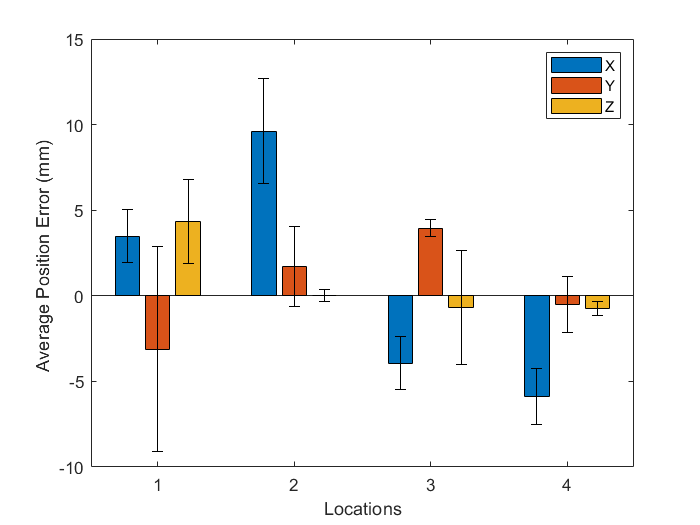

hold on
xlabel("Locations")

ylabel("Average Position Error (mm) ")

%xlabels = categorical({'x 118', 'y 118', 'z 118';'x 280', 'y 280', 'z 280';'x 332', 'y 332', 'z 332' ;'x 333', 'y 333', 'z 333'});
[ngroups,nbars] = size(position_errors);
% Get the x coordinate of the bars
v = nan(nbars, ngroups);
for i = 1:nbars
    v(i,:) = b(i).XEndPoints;
end
% Plot the errorbars
errorbar(v',position_errors,position_deviations,'k','linestyle','none');
hold off

legend(["X","Y","Z"])

clf
X_positions = []


X_positions =

     []



Y_positions = []


Y_positions =

     []



Z_positions = []


Z_positions =

     []



robot_orientation = []


robot_orientation =

     []



std_oreintations_all_tests = []


std_oreintations_all_tests =

     []



error_orientations_all_tests = []


error_orientations_all_tests =

     []



folders = ["109","208","262","280"]

folders = 1×4 string array
    "109"    "208"    "262"    "280"


orientation_error = []


orientation_error =

     []



for j = 1:length(folders)
    robot_positions = [];
    position_cloud = [];
    prefix = folders(j)
    for i =1 : 3
        name = prefix+'\robot_motion_pt_'+prefix+'_' +string(i)+'.bag'
        bag = rosbag(name);
    
        bSel = select(bag,'Topic','/tool_link_ee_pose')
        % 
        msgStructs = readMessages(bSel,'DataFormat','struct');
        
        X = msgStructs{bSel.NumMessages,1}.Transform.Rotation.X;
        Y = msgStructs{bSel.NumMessages,1}.Transform.Rotation.Y
        Z = msgStructs{bSel.NumMessages,1}.Transform.Rotation.Z;
        W = msgStructs{bSel.NumMessages,1}.Transform.Rotation.W;
        robot_quat = [W X Y Z]
        robot_rot_mat = quat2rotm(robot_quat)
        
        
        name = prefix+'/pose_normal_pt_'+prefix+'_'+string(i)+'.bag'
        bag = rosbag(name);
        
        bSel = select(bag,'Topic','/tf_array_out');
        msgStructs = readMessages(bSel,'DataFormat','struct');
        x = msgStructs{bSel.NumMessages,1}.Poses.Orientation.X;
        y = msgStructs{bSel.NumMessages,1}.Poses.Orientation.Y;
        z = msgStructs{bSel.NumMessages,1}.Poses.Orientation.Z;
        w = msgStructs{bSel.NumMessages,1}.Poses.Orientation.W;
        desired_rot_mat = quat2rotm([w x y z])
        err = 0.5*trace(eye(3,3)-desired_rot_mat'*robot_rot_mat)
        orientation_error = [orientation_error; err]   
        
    end
   error_orientations_all_tests = [error_orientations_all_tests;mean(orientation_error)]
   std_oreintations_all_tests = [std_oreintations_all_tests;std(orientation_error)]

end

prefix = "109"

name = "109\robot_motion_pt_109_1.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\109\robot_motion_pt_109_1.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 466
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [466×4 table]


Y = 0.6905

robot_quat =     0.1172    0.7136    0.6905   -0.0166


robot_rot_mat =     0.0459    0.9893    0.1382
    0.9816   -0.0190   -0.1901
   -0.1855    0.1444   -0.9720


name = "109/pose_normal_pt_109_1.bag"

desired_rot_mat =     0.0486    0.9850    0.1659
    0.9651   -0.0035   -0.2617
   -0.2572    0.1728   -0.9508


err = 0.0032

orientation_error = 0.0032

name = "109\robot_motion_pt_109_2.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\109\robot_motion_pt_109_2.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 593
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [593×4 table]


Y = 0.6912

robot_quat =     0.0860    0.7170    0.6912   -0.0280


robot_rot_mat =     0.0430    0.9960    0.0787
    0.9863   -0.0298   -0.1621
   -0.1591    0.0846   -0.9836


name = "109/pose_normal_pt_109_2.bag"

desired_rot_mat =     0.0405    0.9950    0.0908
    0.9808   -0.0223   -0.1935
   -0.1905    0.0969   -0.9769


err = 6.0277e-04

orientation_error =     0.0032
    0.0006


name = "109\robot_motion_pt_109_3.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\109\robot_motion_pt_109_3.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 761
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [761×4 table]


Y = 0.6863

robot_quat =     0.1444    0.7117    0.6863   -0.0406


robot_rot_mat =     0.0548    0.9886    0.1403
    0.9651   -0.0164   -0.2612
   -0.2559    0.1498   -0.9550


name = "109/pose_normal_pt_109_3.bag"

desired_rot_mat =     0.0478    0.9881    0.1463
    0.9720   -0.0123   -0.2347
   -0.2301    0.1534   -0.9610


err = 3.9150e-04

orientation_error =     0.0032
    0.0006
    0.0004


error_orientations_all_tests = 0.0014

std_oreintations_all_tests = 0.0016

prefix = "208"

name = "208\robot_motion_pt_208_1.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\208\robot_motion_pt_208_1.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 696
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [696×4 table]


Y = 0.6873

robot_quat =    -0.0048    0.7171    0.6873    0.1151


robot_rot_mat =     0.0286    0.9870    0.1584
    0.9847   -0.0551    0.1651
    0.1717    0.1513   -0.9735


name = "208/pose_normal_pt_208_1.bag"

desired_rot_mat =     0.0209    0.9741    0.2251
    0.9823   -0.0619    0.1770
    0.1863    0.2174   -0.9581


err = 0.0024

orientation_error =     0.0032
    0.0006
    0.0004
    0.0024


name = "208\robot_motion_pt_208_2.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\208\robot_motion_pt_208_2.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 651
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [651×4 table]


Y = 0.6814

robot_quat =     0.0290    0.7123    0.6814    0.1660


robot_rot_mat =     0.0164    0.9610    0.2760
    0.9803   -0.0698    0.1849
    0.1969    0.2676   -0.9432


name = "208/pose_normal_pt_208_2.bag"

desired_rot_mat =     0.0012    0.9406    0.3394
    0.9739   -0.0781    0.2132
    0.2271    0.3303   -0.9162


err = 0.0028

orientation_error =     0.0032
    0.0006
    0.0004
    0.0024
    0.0028


name = "208\robot_motion_pt_208_3.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\208\robot_motion_pt_208_3.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 777
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [777×4 table]


Y = 0.6831

robot_quat =    -0.0170    0.7105    0.6831    0.1681


robot_rot_mat =     0.0101    0.9764    0.2157
    0.9650   -0.0660    0.2539
    0.2622    0.2056   -0.9429


name = "208/pose_normal_pt_208_3.bag"

desired_rot_mat =    -0.0052    0.9519    0.3063
    0.9605   -0.0805    0.2665
    0.2783    0.2956   -0.9139


err = 0.0047

orientation_error =     0.0032
    0.0006
    0.0004
    0.0024
    0.0028
    0.0047


error_orientations_all_tests =     0.0014
    0.0023


std_oreintations_all_tests =     0.0016
    0.0016


prefix = "262"

name = "262\robot_motion_pt_262_1.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\262\robot_motion_pt_262_1.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 1270
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [1270×4 table]


Y = -0.6792

robot_quat =     0.1871   -0.7031   -0.6792    0.0964


robot_rot_mat =     0.0587    0.9191   -0.3896
    0.9912   -0.0073    0.1322
    0.1186   -0.3940   -0.9114


name = "262/pose_normal_pt_262_1.bag"

desired_rot_mat =     0.0711    0.9102   -0.4080
    0.9863   -0.0031    0.1650
    0.1489   -0.4141   -0.8980


err = 7.9918e-04

orientation_error =     0.0032
    0.0006
    0.0004
    0.0024
    0.0028
    0.0047
    0.0008


name = "262\robot_motion_pt_262_2.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\262\robot_motion_pt_262_2.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 913
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [913×4 table]


Y = -0.6758

robot_quat =     0.1904   -0.7043   -0.6758    0.1054


robot_rot_mat =     0.0645    0.9117   -0.4058
    0.9920   -0.0142    0.1258
    0.1089   -0.4107   -0.9053


name = "262/pose_normal_pt_262_2.bag"

desired_rot_mat =     0.0755    0.8963   -0.4369
    0.9873   -0.0058    0.1587
    0.1397   -0.4434   -0.8854


err = 0.0012

orientation_error =     0.0032
    0.0006
    0.0004
    0.0024
    0.0028
    0.0047
    0.0008
    0.0012


name = "262\robot_motion_pt_262_3.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\262\robot_motion_pt_262_3.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 770
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [770×4 table]


Y = -0.6785

robot_quat =     0.1651   -0.7064   -0.6785    0.1155


robot_rot_mat =     0.0526    0.9205   -0.3871
    0.9968   -0.0247    0.0765
    0.0609   -0.3899   -0.9188


name = "262/pose_normal_pt_262_3.bag"

desired_rot_mat =     0.0667    0.9114   -0.4061
    0.9916   -0.0152    0.1286
    0.1110   -0.4112   -0.9047


err = 0.0017

orientation_error =     0.0032
    0.0006
    0.0004
    0.0024
    0.0028
    0.0047
    0.0008
    0.0012
    0.0017


error_orientations_all_tests =     0.0014
    0.0023
    0.0020


std_oreintations_all_tests =     0.0016
    0.0016
    0.0014


prefix = "280"

name = "280\robot_motion_pt_280_1.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\280\robot_motion_pt_280_1.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 921
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [921×4 table]


Y = -0.6747

robot_quat =     0.1166   -0.7088   -0.6747    0.1699


robot_rot_mat =     0.0319    0.9167   -0.3982
    0.9960   -0.0624   -0.0640
   -0.0836   -0.3946   -0.9150


name = "280/pose_normal_pt_280_1.bag"

desired_rot_mat =     0.0277    0.9093   -0.4153
    0.9962   -0.0596   -0.0641
   -0.0830   -0.4119   -0.9074


err = 1.8232e-04

orientation_error =     0.0032
    0.0006
    0.0004
    0.0024
    0.0028
    0.0047
    0.0008
    0.0012
    0.0017
    0.0002


name = "280\robot_motion_pt_280_2.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\280\robot_motion_pt_280_2.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 726
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [726×4 table]


Y = -0.6751

robot_quat =     0.1081   -0.7078   -0.6751    0.1776


robot_rot_mat =     0.0254    0.9173   -0.3974
    0.9941   -0.0652   -0.0868
   -0.1055   -0.3929   -0.9135


name = "280/pose_normal_pt_280_2.bag"

desired_rot_mat =     0.0161    0.8960   -0.4438
    0.9949   -0.0585   -0.0821
   -0.0995   -0.4402   -0.8924


err = 0.0014

orientation_error =     0.0032
    0.0006
    0.0004
    0.0024
    0.0028
    0.0047
    0.0008
    0.0012
    0.0017
    0.0002


name = "280\robot_motion_pt_280_3.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\280\robot_motion_pt_280_3.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 724
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [724×4 table]


Y = -0.6741

robot_quat =     0.1083   -0.7082   -0.6741    0.1796


robot_rot_mat =     0.0266    0.9159   -0.4004
    0.9937   -0.0677   -0.0888
   -0.1085   -0.3955   -0.9120


name = "280/pose_normal_pt_280_3.bag"

desired_rot_mat = 3×3
    0.0137    0.9019   -0.4317
    0.9936   -0.0609   -0.0955
   -0.1124   -0.4276   -0.8970


err = 6.7432e-04

orientation_error = 12×1
    0.0032
    0.0006
    0.0004
    0.0024
    0.0028
    0.0047
    0.0008
    0.0012
    0.0017
    0.0002


error_orientations_all_tests = 4×1
    0.0014
    0.0023
    0.0020
    0.0017


std_oreintations_all_tests = 4×1
    0.0016
    0.0016
    0.0014
    0.0014



%bar(categorical({'forehead','left chin','right chin','cheek'}),position_errors','grouped')
b = bar(error_orientations_all_tests)

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [0 0.4470 0.7410]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2 3 4]
        YData: [0.0014 0.0023 0.0020 0.0017]

  Show all properties


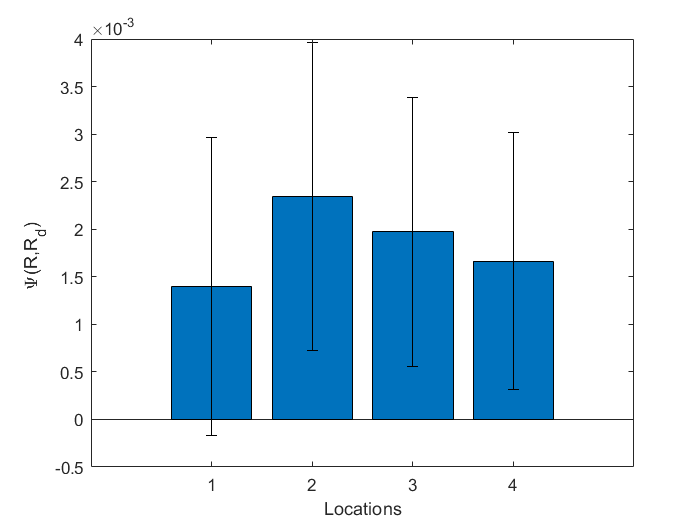

hold on
xlabel("Locations")

ylabel("\Psi(R,R_d) ")

%xlabels = categorical({'x 118', 'y 118', 'z 118';'x 280', 'y 280', 'z 280';'x 332', 'y 332', 'z 332' ;'x 333', 'y 333', 'z 333'});
[ngroups,nbars] = size(error_orientations_all_tests);
% Get the x coordinate of the bars
v = nan(nbars, ngroups);
for i = 1:nbars
    v(i,:) = b(i).XEndPoints;
end
% Plot the errorbars
errorbar(v',error_orientations_all_tests,std_oreintations_all_tests,'k','linestyle','none');
hold off




clf
X_positions = []


X_positions =

     []



Y_positions = []


Y_positions =

     []



Z_positions = []


Z_positions =

     []



robot_orientation = []


robot_orientation =

     []



std_oreintations_all_tests = []


std_oreintations_all_tests =

     []



error_orientations_all_tests = []


error_orientations_all_tests =

     []



folders = ["109","208","262","280"]

folders = 1×4 string array
    "109"    "208"    "262"    "280"


orientation_error = []


orientation_error =

     []



orientation_error_eul = []


orientation_error_eul =

     []



desired_orientation = []


desired_orientation =

     []



robot_orientations = []


robot_orientations =

     []



for j = 1:length(folders)
    robot_positions = [];
    position_cloud = [];
    prefix = folders(j)
    for i =1 : 3
        name = prefix+'\robot_motion_pt_'+prefix+'_' +string(i)+'.bag'
        bag = rosbag(name);
    
        bSel = select(bag,'Topic','/tool_link_ee_pose')
        % 
        msgStructs = readMessages(bSel,'DataFormat','struct');
        
        X = msgStructs{bSel.NumMessages,1}.Transform.Rotation.X;
        Y = msgStructs{bSel.NumMessages,1}.Transform.Rotation.Y
        Z = msgStructs{bSel.NumMessages,1}.Transform.Rotation.Z;
        W = msgStructs{bSel.NumMessages,1}.Transform.Rotation.W;
        robot_quat = [W X Y Z]
        robot_eul = quat2eul(robot_quat,'ZYX')*180/pi
        robot_rot_mat = quat2rotm(robot_quat)
        robot_orientations = [robot_orientations;robot_eul]
        
        name = prefix+'/pose_normal_pt_'+prefix+'_'+string(i)+'.bag'
        bag = rosbag(name);
        
        bSel = select(bag,'Topic','/tf_array_out');
        msgStructs = readMessages(bSel,'DataFormat','struct');
        x = msgStructs{bSel.NumMessages,1}.Poses.Orientation.X;
        y = msgStructs{bSel.NumMessages,1}.Poses.Orientation.Y;
        z = msgStructs{bSel.NumMessages,1}.Poses.Orientation.Z;
        w = msgStructs{bSel.NumMessages,1}.Poses.Orientation.W;
        desired_rot_mat = quat2rotm([w x y z])
        desired_eul = quat2eul([w x y z],'ZYX')*180/pi
        desired_orientation = [desired_orientation;desired_eul]
    end
   orientation_error = desired_orientation - robot_orientations 
   error_orientations_all_tests = [error_orientations_all_tests;mean(orientation_error)]
   std_oreintations_all_tests = [std_oreintations_all_tests;std(orientation_error)]

end

prefix = "109"

name = "109\robot_motion_pt_109_1.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\109\robot_motion_pt_109_1.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 466
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [466×4 table]


Y = 0.6905

robot_quat =     0.1172    0.7136    0.6905   -0.0166


robot_eul =    87.3232   10.6893  171.5504


robot_rot_mat =     0.0459    0.9893    0.1382
    0.9816   -0.0190   -0.1901
   -0.1855    0.1444   -0.9720


robot_orientations =    87.3232   10.6893  171.5504


name = "109/pose_normal_pt_109_1.bag"

desired_rot_mat =     0.0486    0.9850    0.1659
    0.9651   -0.0035   -0.2617
   -0.2572    0.1728   -0.9508


desired_eul =    87.1178   14.9046  169.6993


desired_orientation =    87.1178   14.9046  169.6993


name = "109\robot_motion_pt_109_2.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\109\robot_motion_pt_109_2.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 593
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [593×4 table]


Y = 0.6912

robot_quat =     0.0860    0.7170    0.6912   -0.0280


robot_eul =    87.5033    9.1540  175.0855


robot_rot_mat =     0.0430    0.9960    0.0787
    0.9863   -0.0298   -0.1621
   -0.1591    0.0846   -0.9836


robot_orientations =    87.3232   10.6893  171.5504
   87.5033    9.1540  175.0855


name = "109/pose_normal_pt_109_2.bag"

desired_rot_mat =     0.0405    0.9950    0.0908
    0.9808   -0.0223   -0.1935
   -0.1905    0.0969   -0.9769


desired_eul =    87.6362   10.9827  174.3361


desired_orientation =    87.1178   14.9046  169.6993
   87.6362   10.9827  174.3361


name = "109\robot_motion_pt_109_3.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\109\robot_motion_pt_109_3.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 761
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [761×4 table]


Y = 0.6863

robot_quat =     0.1444    0.7117    0.6863   -0.0406


robot_eul =    86.7504   14.8282  171.0873


robot_rot_mat =     0.0548    0.9886    0.1403
    0.9651   -0.0164   -0.2612
   -0.2559    0.1498   -0.9550


robot_orientations =    87.3232   10.6893  171.5504
   87.5033    9.1540  175.0855
   86.7504   14.8282  171.0873


name = "109/pose_normal_pt_109_3.bag"

desired_rot_mat =     0.0478    0.9881    0.1463
    0.9720   -0.0123   -0.2347
   -0.2301    0.1534   -0.9610


desired_eul =    87.1817   13.3027  170.9309


desired_orientation =    87.1178   14.9046  169.6993
   87.6362   10.9827  174.3361
   87.1817   13.3027  170.9309


orientation_error =    -0.2053    4.2153   -1.8511
    0.1329    1.8287   -0.7493
    0.4313   -1.5255   -0.1564


error_orientations_all_tests =     0.1196    1.5061   -0.9190


std_oreintations_all_tests =     0.3185    2.8840    0.8600


prefix = "208"

name = "208\robot_motion_pt_208_1.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\208\robot_motion_pt_208_1.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 696
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [696×4 table]


Y = 0.6873

robot_quat =    -0.0048    0.7171    0.6873    0.1151


robot_eul =    88.3341   -9.8844  171.1670


robot_rot_mat =     0.0286    0.9870    0.1584
    0.9847   -0.0551    0.1651
    0.1717    0.1513   -0.9735


robot_orientations =    87.3232   10.6893  171.5504
   87.5033    9.1540  175.0855
   86.7504   14.8282  171.0873
   88.3341   -9.8844  171.1670


name = "208/pose_normal_pt_208_1.bag"

desired_rot_mat =     0.0209    0.9741    0.2251
    0.9823   -0.0619    0.1770
    0.1863    0.2174   -0.9581


desired_eul =    88.7833  -10.7374  167.2161


desired_orientation =    87.1178   14.9046  169.6993
   87.6362   10.9827  174.3361
   87.1817   13.3027  170.9309
   88.7833  -10.7374  167.2161


name = "208\robot_motion_pt_208_2.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\208\robot_motion_pt_208_2.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 651
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [651×4 table]


Y = 0.6814

robot_quat =     0.0290    0.7123    0.6814    0.1660


robot_eul =    89.0421  -11.3578  164.1621


robot_rot_mat =     0.0164    0.9610    0.2760
    0.9803   -0.0698    0.1849
    0.1969    0.2676   -0.9432


robot_orientations =    87.3232   10.6893  171.5504
   87.5033    9.1540  175.0855
   86.7504   14.8282  171.0873
   88.3341   -9.8844  171.1670
   89.0421  -11.3578  164.1621


name = "208/pose_normal_pt_208_2.bag"

desired_rot_mat =     0.0012    0.9406    0.3394
    0.9739   -0.0781    0.2132
    0.2271    0.3303   -0.9162


desired_eul =    89.9320  -13.1248  160.1750


desired_orientation =    87.1178   14.9046  169.6993
   87.6362   10.9827  174.3361
   87.1817   13.3027  170.9309
   88.7833  -10.7374  167.2161
   89.9320  -13.1248  160.1750


name = "208\robot_motion_pt_208_3.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\208\robot_motion_pt_208_3.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 777
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [777×4 table]


Y = 0.6831

robot_quat =    -0.0170    0.7105    0.6831    0.1681


robot_eul =    89.4017  -15.1980  167.7015


robot_rot_mat =     0.0101    0.9764    0.2157
    0.9650   -0.0660    0.2539
    0.2622    0.2056   -0.9429


robot_orientations =    87.3232   10.6893  171.5504
   87.5033    9.1540  175.0855
   86.7504   14.8282  171.0873
   88.3341   -9.8844  171.1670
   89.0421  -11.3578  164.1621
   89.4017  -15.1980  167.7015


name = "208/pose_normal_pt_208_3.bag"

desired_rot_mat =    -0.0052    0.9519    0.3063
    0.9605   -0.0805    0.2665
    0.2783    0.2956   -0.9139


desired_eul =    90.3107  -16.1589  162.0758


desired_orientation =    87.1178   14.9046  169.6993
   87.6362   10.9827  174.3361
   87.1817   13.3027  170.9309
   88.7833  -10.7374  167.2161
   89.9320  -13.1248  160.1750
   90.3107  -16.1589  162.0758


orientation_error =    -0.2053    4.2153   -1.8511
    0.1329    1.8287   -0.7493
    0.4313   -1.5255   -0.1564
    0.4491   -0.8530   -3.9508
    0.8899   -1.7670   -3.9871
    0.9090   -0.9609   -5.6257


error_orientations_all_tests =     0.1196    1.5061   -0.9190
    0.4345    0.1563   -2.7201


std_oreintations_all_tests =     0.3185    2.8840    0.8600
    0.4320    2.3693    2.1342


prefix = "262"

name = "262\robot_motion_pt_262_1.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\262\robot_motion_pt_262_1.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 1270
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [1270×4 table]


Y = -0.6792

robot_quat =     0.1871   -0.7031   -0.6792    0.0964


robot_eul = 1×3
   86.6116   -6.8129 -156.6241


robot_rot_mat = 3×3
    0.0587    0.9191   -0.3896
    0.9912   -0.0073    0.1322
    0.1186   -0.3940   -0.9114


robot_orientations = 7×3
   87.3232   10.6893  171.5504
   87.5033    9.1540  175.0855
   86.7504   14.8282  171.0873
   88.3341   -9.8844  171.1670
   89.0421  -11.3578  164.1621
   89.4017  -15.1980  167.7015
   86.6116   -6.8129 -156.6241


name = "262/pose_normal_pt_262_1.bag"

desired_rot_mat = 3×3
    0.0711    0.9102   -0.4080
    0.9863   -0.0031    0.1650
    0.1489   -0.4141   -0.8980


desired_eul = 1×3
   85.8786   -8.5653 -155.2417


desired_orientation = 7×3
   87.1178   14.9046  169.6993
   87.6362   10.9827  174.3361
   87.1817   13.3027  170.9309
   88.7833  -10.7374  167.2161
   89.9320  -13.1248  160.1750
   90.3107  -16.1589  162.0758
   85.8786   -8.5653 -155.2417


name = "262\robot_motion_pt_262_2.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\262\robot_motion_pt_262_2.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 913
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [913×4 table]


Y = -0.6758

robot_quat = 1×4
    0.1904   -0.7043   -0.6758    0.1054


robot_eul = 1×3
   86.2801   -6.2536 -155.5986


robot_rot_mat = 3×3
    0.0645    0.9117   -0.4058
    0.9920   -0.0142    0.1258
    0.1089   -0.4107   -0.9053


robot_orientations = 8×3
   87.3232   10.6893  171.5504
   87.5033    9.1540  175.0855
   86.7504   14.8282  171.0873
   88.3341   -9.8844  171.1670
   89.0421  -11.3578  164.1621
   89.4017  -15.1980  167.7015
   86.6116   -6.8129 -156.6241
   86.2801   -6.2536 -155.5986


name = "262/pose_normal_pt_262_2.bag"

desired_rot_mat = 3×3
    0.0755    0.8963   -0.4369
    0.9873   -0.0058    0.1587
    0.1397   -0.4434   -0.8854


desired_eul = 1×3
   85.6260   -8.0318 -153.4005


desired_orientation = 8×3
   87.1178   14.9046  169.6993
   87.6362   10.9827  174.3361
   87.1817   13.3027  170.9309
   88.7833  -10.7374  167.2161
   89.9320  -13.1248  160.1750
   90.3107  -16.1589  162.0758
   85.8786   -8.5653 -155.2417
   85.6260   -8.0318 -153.4005


name = "262\robot_motion_pt_262_3.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\262\robot_motion_pt_262_3.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 770
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [770×4 table]


Y = -0.6785

robot_quat = 1×4
    0.1651   -0.7064   -0.6785    0.1155


robot_eul = 1×3
   86.9816   -3.4893 -157.0069


robot_rot_mat = 3×3
    0.0526    0.9205   -0.3871
    0.9968   -0.0247    0.0765
    0.0609   -0.3899   -0.9188


robot_orientations = 9×3
   87.3232   10.6893  171.5504
   87.5033    9.1540  175.0855
   86.7504   14.8282  171.0873
   88.3341   -9.8844  171.1670
   89.0421  -11.3578  164.1621
   89.4017  -15.1980  167.7015
   86.6116   -6.8129 -156.6241
   86.2801   -6.2536 -155.5986
   86.9816   -3.4893 -157.0069


name = "262/pose_normal_pt_262_3.bag"

desired_rot_mat = 3×3
    0.0667    0.9114   -0.4061
    0.9916   -0.0152    0.1286
    0.1110   -0.4112   -0.9047


desired_eul = 1×3
   86.1543   -6.3732 -155.5562


desired_orientation = 9×3
   87.1178   14.9046  169.6993
   87.6362   10.9827  174.3361
   87.1817   13.3027  170.9309
   88.7833  -10.7374  167.2161
   89.9320  -13.1248  160.1750
   90.3107  -16.1589  162.0758
   85.8786   -8.5653 -155.2417
   85.6260   -8.0318 -153.4005
   86.1543   -6.3732 -155.5562


orientation_error = 9×3
   -0.2053    4.2153   -1.8511
    0.1329    1.8287   -0.7493
    0.4313   -1.5255   -0.1564
    0.4491   -0.8530   -3.9508
    0.8899   -1.7670   -3.9871
    0.9090   -0.9609   -5.6257
   -0.7330   -1.7524    1.3823
   -0.6541   -1.7782    2.1981
   -0.8273   -2.8839    1.4506


error_orientations_all_tests = 3×3
    0.1196    1.5061   -0.9190
    0.4345    0.1563   -2.7201
    0.0436   -0.6085   -1.2544


std_oreintations_all_tests = 3×3
    0.3185    2.8840    0.8600
    0.4320    2.3693    2.1342
    0.6799    2.2201    2.7806


prefix = "280"

name = "280\robot_motion_pt_280_1.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\280\robot_motion_pt_280_1.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 921
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [921×4 table]


Y = -0.6747

robot_quat = 1×4
    0.1166   -0.7088   -0.6747    0.1699


robot_eul = 1×3
   88.1682    4.7940 -156.6728


robot_rot_mat = 3×3
    0.0319    0.9167   -0.3982
    0.9960   -0.0624   -0.0640
   -0.0836   -0.3946   -0.9150


robot_orientations = 10×3
   87.3232   10.6893  171.5504
   87.5033    9.1540  175.0855
   86.7504   14.8282  171.0873
   88.3341   -9.8844  171.1670
   89.0421  -11.3578  164.1621
   89.4017  -15.1980  167.7015
   86.6116   -6.8129 -156.6241
   86.2801   -6.2536 -155.5986
   86.9816   -3.4893 -157.0069
   88.1682    4.7940 -156.6728


name = "280/pose_normal_pt_280_1.bag"

desired_rot_mat = 3×3
    0.0277    0.9093   -0.4153
    0.9962   -0.0596   -0.0641
   -0.0830   -0.4119   -0.9074


desired_eul = 1×3
   88.4084    4.7638 -155.5856


desired_orientation = 10×3
   87.1178   14.9046  169.6993
   87.6362   10.9827  174.3361
   87.1817   13.3027  170.9309
   88.7833  -10.7374  167.2161
   89.9320  -13.1248  160.1750
   90.3107  -16.1589  162.0758
   85.8786   -8.5653 -155.2417
   85.6260   -8.0318 -153.4005
   86.1543   -6.3732 -155.5562
   88.4084    4.7638 -155.5856


name = "280\robot_motion_pt_280_2.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\280\robot_motion_pt_280_2.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 726
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [726×4 table]


Y = -0.6751

robot_quat = 1×4
    0.1081   -0.7078   -0.6751    0.1776


robot_eul = 1×3
   88.5337    6.0549 -156.7289


robot_rot_mat = 3×3
    0.0254    0.9173   -0.3974
    0.9941   -0.0652   -0.0868
   -0.1055   -0.3929   -0.9135


robot_orientations = 11×3
   87.3232   10.6893  171.5504
   87.5033    9.1540  175.0855
   86.7504   14.8282  171.0873
   88.3341   -9.8844  171.1670
   89.0421  -11.3578  164.1621
   89.4017  -15.1980  167.7015
   86.6116   -6.8129 -156.6241
   86.2801   -6.2536 -155.5986
   86.9816   -3.4893 -157.0069
   88.1682    4.7940 -156.6728


name = "280/pose_normal_pt_280_2.bag"

desired_rot_mat = 3×3
    0.0161    0.8960   -0.4438
    0.9949   -0.0585   -0.0821
   -0.0995   -0.4402   -0.8924


desired_eul = 1×3
   89.0723    5.7114 -153.7435


desired_orientation = 11×3
   87.1178   14.9046  169.6993
   87.6362   10.9827  174.3361
   87.1817   13.3027  170.9309
   88.7833  -10.7374  167.2161
   89.9320  -13.1248  160.1750
   90.3107  -16.1589  162.0758
   85.8786   -8.5653 -155.2417
   85.6260   -8.0318 -153.4005
   86.1543   -6.3732 -155.5562
   88.4084    4.7638 -155.5856


name = "280\robot_motion_pt_280_3.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Alex_Tests_v2\Alex_Tests_v2\280\robot_motion_pt_280_3.bag'
          StartTime: 1.6972e+09
            EndTime: 1.6972e+09
        NumMessages: 724
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [724×4 table]


Y = -0.6741

robot_quat = 1×4
    0.1083   -0.7082   -0.6741    0.1796


robot_eul = 1×3
   88.4675    6.2275 -156.5533


robot_rot_mat = 3×3
    0.0266    0.9159   -0.4004
    0.9937   -0.0677   -0.0888
   -0.1085   -0.3955   -0.9120


robot_orientations = 12×3
   87.3232   10.6893  171.5504
   87.5033    9.1540  175.0855
   86.7504   14.8282  171.0873
   88.3341   -9.8844  171.1670
   89.0421  -11.3578  164.1621
   89.4017  -15.1980  167.7015
   86.6116   -6.8129 -156.6241
   86.2801   -6.2536 -155.5986
   86.9816   -3.4893 -157.0069
   88.1682    4.7940 -156.6728


name = "280/pose_normal_pt_280_3.bag"

desired_rot_mat = 3×3
    0.0137    0.9019   -0.4317
    0.9936   -0.0609   -0.0955
   -0.1124   -0.4276   -0.8970


desired_eul = 1×3
   89.2077    6.4558 -154.5134


desired_orientation = 12×3
   87.1178   14.9046  169.6993
   87.6362   10.9827  174.3361
   87.1817   13.3027  170.9309
   88.7833  -10.7374  167.2161
   89.9320  -13.1248  160.1750
   90.3107  -16.1589  162.0758
   85.8786   -8.5653 -155.2417
   85.6260   -8.0318 -153.4005
   86.1543   -6.3732 -155.5562
   88.4084    4.7638 -155.5856


orientation_error = 12×3
   -0.2053    4.2153   -1.8511
    0.1329    1.8287   -0.7493
    0.4313   -1.5255   -0.1564
    0.4491   -0.8530   -3.9508
    0.8899   -1.7670   -3.9871
    0.9090   -0.9609   -5.6257
   -0.7330   -1.7524    1.3823
   -0.6541   -1.7782    2.1981
   -0.8273   -2.8839    1.4506
    0.2401   -0.0302    1.0872


error_orientations_all_tests = 4×3
    0.1196    1.5061   -0.9190
    0.4345    0.1563   -2.7201
    0.0436   -0.6085   -1.2544
    0.1593   -0.4685   -0.4314


std_oreintations_all_tests = 4×3
    0.3185    2.8840    0.8600
    0.4320    2.3693    2.1342
    0.6799    2.2201    2.7806
    0.6257    1.9141    2.8290



b = bar(error_orientations_all_tests,'grouped')

b =   1×3 Bar array:

    Bar    Bar    Bar


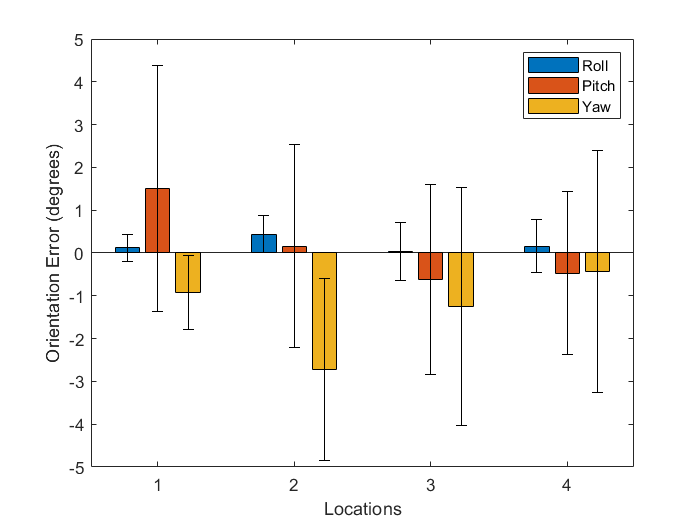

%b = bar(error_orientations_all_tests)
hold on
xlabel("Locations")

ylabel("Orientation Error (degrees)")

%xlabels = categorical({'x 118', 'y 118', 'z 118';'x 280', 'y 280', 'z 280';'x 332', 'y 332', 'z 332' ;'x 333', 'y 333', 'z 333'});
[ngroups,nbars] = size(error_orientations_all_tests);
% Get the x coordinate of the bars
v = nan(nbars, ngroups);
for i = 1:nbars
    v(i,:) = b(i).XEndPoints;
end
% Plot the errorbars
errorbar(v',error_orientations_all_tests,std_oreintations_all_tests,'k','linestyle','none');
hold off
legend(["Roll","Pitch","Yaw"])